# `Tratamiento de Datos Precisos Actualizados`

Trataremos el archivo `igs95p02.erp` extraído de la [NASA's Archive of Space Geodesy Data](https://cddis.nasa.gov/archive/gnss/products/). Contiene los archivos IGS erp finales acumulados comenzando en  la semana GPS 0860 o MJD 50264.5.

### `Tablas de datos`

Definamos la tabla `tablaP` que almacenará los siguientes datos que extraeremos de los archivos en la carpeta` /PRECISOS`:

`fecha, X-polo, Y-polo, UT1-UTC, Xsig, Ysig, UTsig`.

Tomaremos datos desde 51545.50 a 58383.50 en fecha juliana modificada. 

Primero, definimos el tipo de dato que almacenará cada columna y su nombre.

varTipos = ["double","double","double","double","double","double","double"];
varNames = ["Fecha", "X", "Y", "UT", "X-SIG", "Y-SIG", "UT-SIG"];

Segundo, una variable auxiliar en el que almacenaremos el número de columnas.

sz = [1 length(varNames)];

Finalmente, definimos la tabla con lo citado anteriormente.

tablaP = table('Size',sz,'VariableTypes',varTipos,'VariableNames',varNames);

A continuación, la variable auxiliar `fila` para almacenar el nº de filas que tiene la tabla.

fila = 0;

### `Código Realizado`

Definimos en primer lugar la ruta donde se encuentra nuestro archivo de datos en la variable `directorio_raiz`. También una variable, `directorio_datos`, con el nombre de la carpeta donde están los datos. Finalmente, la ruta completa se almacena en `pathe_entrada`.

directorio_raiz ='/home/desk-chaguarma/Documents/UNI/SAG/PRACTICAS/PR1/'; 
directorio_datos = 'PRECISOS_ACTUALIZADO/';
directorio_sal= 'SALIDA/';
directorio_diag= 'DIAGRAMAS/';

pathe_entrada=[directorio_raiz directorio_datos]; 
pathe_diag=[directorio_raiz directorio_diag];

Primero, la función `fullfile` crea una especificación de archivo completa a partir de la carpeta y nombres de archivo especificados. Finalmente, almacenamos en `archivos` la enumeración dada por la función `dir`. Esta enumera los archivos y carpetas que coinciden con el nombre dado.

archivos = dir(fullfile(pathe_entrada, "ig*"));

Tras lo anterior, almacenamos el número de archivos reconocidos en `numero`.

numero=size(archivos) 

numero =      1     1


Para obtener los datos de los archivos .erp, leeremos línea por línea estos documentos. Para llegar a las líneas de datos, saltaremos un número determinado de líneas de cabecera. 

Hay dos formatos de cabecera en los archivos .erp, con su número específico de líneas a omitir. Hemos almacenado estos números en `elim` y `elimEOP`. 

elim = 1;
elimEOP = 2;

Para leer cada archivo, realizaremos un bucle `for` en el que leeremos del primer al último archivo reconocido. En cada uno, definiremos la variable `cabe` para controlar si hemos leido la cabecera y ha encontrado los datos o si ha leido el documento y no ha encontrado datos.

for i=1:numero(1)
    % Tomamos el nombre del archivo i
    fichero_entrada=[archivos(i).name];
    % Abrimos el archivo i empleando fopen.
    fidin = fopen([pathe_entrada fichero_entrada], 'r');
    
    cabe=0;

Distinguiremos el formato del documento abierto en `fidin`, Tras ello, con un bucle `for`, saltamos el número de líneas necesarias. En caso de no seguir un formato (`cabe == 0`), se devuelve el nombre del archivo y paramos el bucle.

    while ~feof(fidin) 
        registro = fgetl(fidin);
        
        if length(registro)>=3
            if registro(1:3) == 'EOP'
                % Nos saltamos elimEOP filas
                for j = 1:elimEOP
                    fgetl(fidin);
                end
                cabe = 1;
                break
            elseif (length(registro)>=5) & (registro(1:5) == '  MJD')
                % Nos saltamos elim filas
                for j = 1:elim
                    fgetl(fidin);
                end
                cabe = 1;
                break
            end
        end
    
    end

Una vez omitidas las líneas de cabecera, identificado el patrón del archivo, obtenemos los datos de cada fila. 

Para ello, emplearemos un bucle `while`, que lea el archivo hasta su final. 

Leemos la línea con la función `fgetl` y tomamos los tres primeros caracteres para controlar si hemos llegado al final del archivo. A partir de una función `if` controlamos si ha llegado al final.

    if cabe == 0
        break
    end

    while ~feof(fidin) 
        registro = fgetl(fidin);
        
        if registro(1:3) == 'EOF'
            break

Una vez comprobado que no es el final del documento, con la función `split`, dividimos la fila de datos que estan separados por espacios y los almacenamos como un vector de caracteres en `registro`. Además, al añadir una nueva fila, aumentamos el contador `fila`,

        else
            fila = fila + 1;
            registro = split(registro);
            registro = registro(1:8);

Para almacenar la fecha, primero transformamos el dato de fecha juliana modificada a formato año-mes-día (yyyy-MM-dd). Tras ello, a partir de la función `date2doy` obtenida [aquí](https://es.mathworks.com/matlabcentral/fileexchange/18316-date-to-decimal-day-of-year?s_tid=srchtitle_date2doy_1), transformamos la fecha a año con decimal.

            fecha = datetime(str2num(cell2mat(registro(1))), 'ConvertFrom','mjd', 'Format','yyyy-MM-dd');
            
            [doy,frac] = date2doy(datenum(fecha));
      
            frac = extractAfter(string(frac),1);
            fecha = strcat(string(year(fecha)),frac);

Finalmente, almacenamos los datos deseados en la tabla definida anteriormente. Almacenamos los datos en formato `double`.

            tablaP(fila,:) = {double(string(fecha)), double(string(registro(2)))*10^(-6), double(string(registro(3)))*10^(-6), double(string(registro(4)))*10^(-7), double(string(registro(6))), double(string(registro(7))), double(string(registro(8)))};
        end
    end
    fclose(fidin); 
end 
%fclose(fidsal); 

### `Tabla Obtenida`

Aquí tenemos la tabla obtenida y el número de datos almacenados.

fila

fila = 9709

tablaP(1:8,:)

ans = 8×7 table
    Fecha        X          Y         UT       X-SIG    Y-SIG    UT-SIG
    ______    _______    _______    _______    _____    _____    ______

    1996.5    0.17743    0.54909    0.18771      70      200       0   
    1996.5    0.18071    0.54646    0.18654      50      200       0   
    1996.5    0.18383    0.54366    0.18534     100      170       0   
    1996.5    0.18699    0.54091    0.18404     100      170       0   
    1996.5    0.19013    0.53797    0.18264     100      150       0   
    1996.5    0.19381    0.53497     0.1812      80      170       0   
    1996.5    0.19777    0.53256    0.17976      60      170       0   
    1996.5    0.20184    0.53032    0.17837      70      210       0   


Guardamos la tabla `tablaP` de los datos precisos.

save([directorio_raiz directorio_sal, 'tablaPrecisosActualizado.mat'],"tablaP")

### `Graficando Datos`

En esta gráfica representamos la variación de posición en X del polo durante el tiempo.

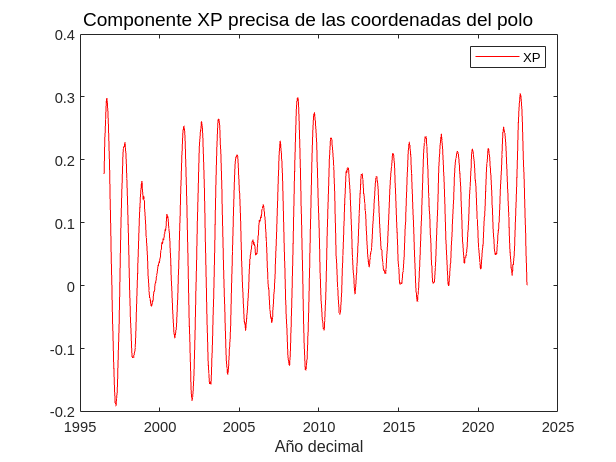

figure;
plot(tablaP.Fecha,tablaP.X,"red")
legend("XP")
xlabel('Año decimal')
sgtitle('Componente XP precisa de las coordenadas del polo')

En esta gráfica representamos la variación de posición en Y del polo durante el tiempo.

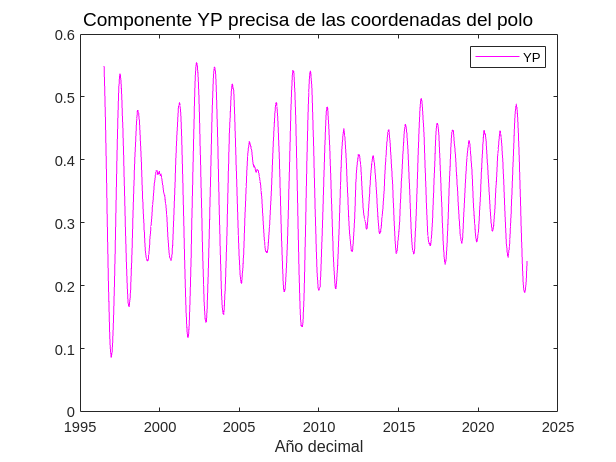

figure;
plot(tablaP.Fecha,tablaP.Y,"magenta")
legend("YP")
xlabel('Año decimal')
sgtitle('Componente YP precisa de las coordenadas del polo')

Se puede ver que ambas componentes varían de forma parecida, pero la componente `Y` toma valores mayores.

Ahora vemos la relación de posición de X e Y, y vemos que la posición del polo va variando describiendo circunferencias.

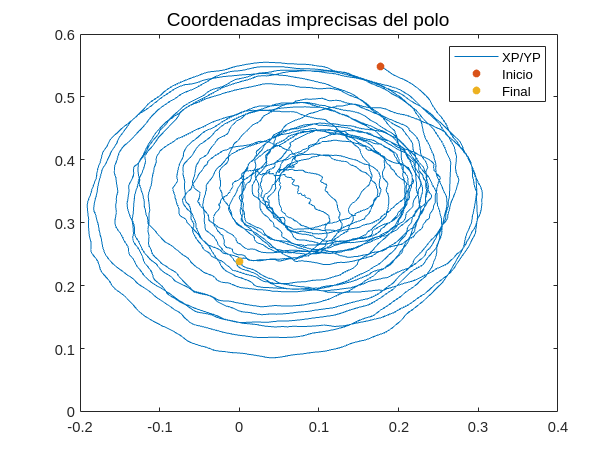

figure;
plot(tablaP.X,tablaP.Y)
hold on
plot(tablaP.X(1),tablaP.Y(1),".",'MarkerSize',16)
plot(tablaP.X(fila),tablaP.Y(fila),".",'MarkerSize',16)
legend("XP/YP","Inicio","Final")
sgtitle('Coordenadas imprecisas del polo')
hold off

Vemos que el polo describe elipses irregulares, superponiéndose.

Por último, graficamos las diferencias  de UT1, que es la corrección de UT0 por el efecto del movimiento polar en la longitud del sitio de observación, y UTC, que es el tiempo universal coordinado.

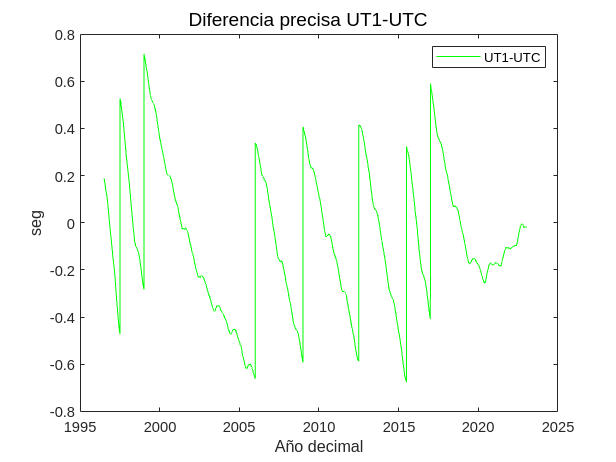

figure;
plot(tablaP.Fecha,tablaP.UT,"green")
legend("UT1-UTC")
xlabel('Año decimal')
ylabel('seg')
sgtitle('Diferencia precisa UT1-UTC')

Finalmente, para el tiempo observamos que su corrección hace una gráfica escalonada.

*Adrián Fernández Tejada - Adrián Sánchez Loureiro*

## `Funciones definidas`

Aquí tenemos la función citada anteriormente, que nos transforma la fecha a un número decimal.

function [doy,fraction] = date2doy(inputDate)
%DATE2DOY  Converts the date to decimal day of the year.
%   [doy,fraction] = date2doy(inputDate)
%
%   Descriptions of Input Variables:
%   inputDate:  Input date as a MATLAB serial datenumber
%
%   Descriptions of Output Variables:
%   doy: Decimal day of the year. For instance, an output of 1.5 would 
%       indicate that the time is noon on January 1.
%   fraction: Outputs tratas_MAM_2_3he fraction of a year that has elapsed by the input
%       date.
%
%   Example(s):
%   >> [doy,frac] = date2doy(datenum('1/25/2004'));
%
%   See also:

% Author: Anthony Kendall
% Contact: anthony [dot] kendall [at] gmail [dot] com
% Created: 2008-03-11
% Copyright 2008 Michigan State University.

%Want inputs in rowwise format
[doy,fraction] = deal(zeros(size(inputDate)));
inputDate = inputDate(:);

%Parse the inputDate
[dateVector] = datevec(inputDate);

%Set everything in the date vector to 0 except for the year
dateVector(:,2:end) = 0;
dateYearBegin = datenum(dateVector);

%Calculate the day of the year
doyRow = inputDate - dateYearBegin;

%Optionally, calculate the fraction of the year that has elapsed
flagFrac = (nargout==2);
if flagFrac
    %Set the date as the end of the year
    dateVector(:,1) = dateVector(:,1) + 1;
    dateYearEnd = datenum(dateVector);
    fracRow = (doyRow - 1) ./ (dateYearEnd - dateYearBegin);
end

%Fill appropriately-sized output array
doy(:) = doyRow;
if flagFrac
    fraction(:) = fracRow;
end
end